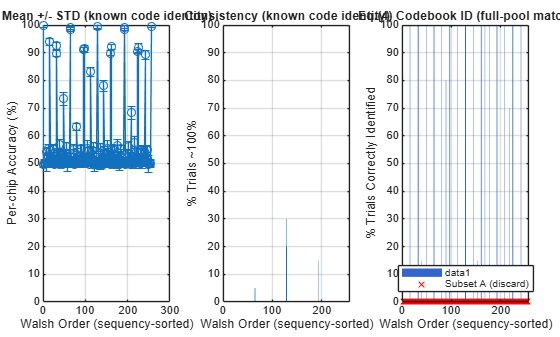

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1           99.766         0.49735          80            100              0               0                 1     
         129                4           49.512          1.0286           0              0              1               1                30     
         193                6            49.98         0.92677           0              0              2             

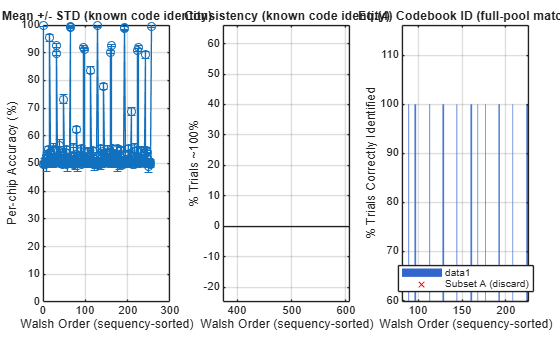

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1           99.824         0.39011          80            100              0               0                 1     
         129                4           49.766         0.97677           0              0              1               1                31     
         193                6           50.059         0.90751           0              0              2             

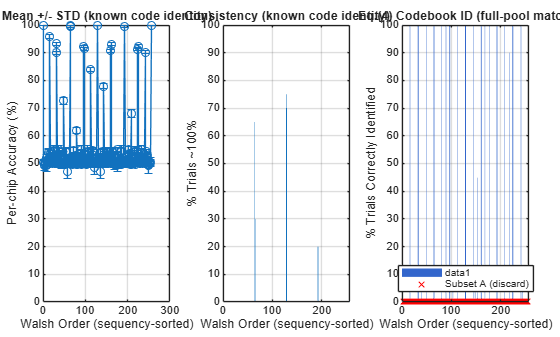

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1           99.961         0.17469          95            100              0               0                 1     
         129                4           50.527         0.94224           0              0              1               1                33     
         193                6           49.922          1.2327           0              0              2             

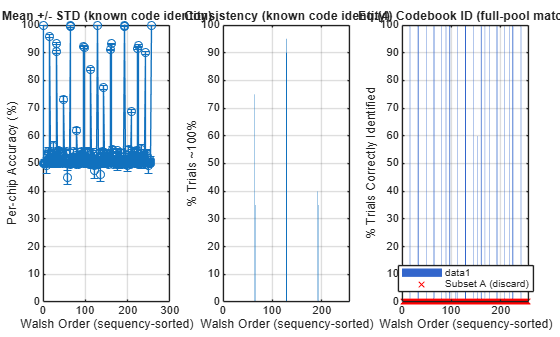

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1            99.98        0.087346          95            100              0               0                 1     
         129                4           50.137            0.72           0              0              1               1                30     
         193                6           50.449         0.96747           0              0              2             

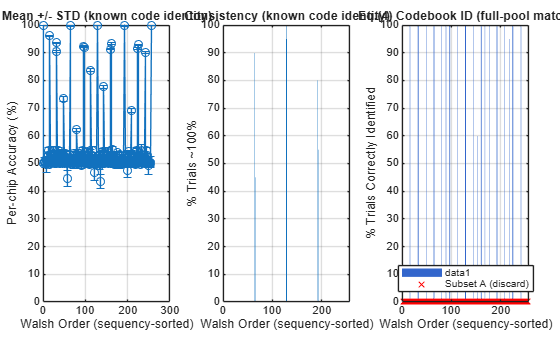

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1              100               0         100            100              0               0                 1     
         129                4           50.059         0.91632           0              0              1               1                29     
         193                6           50.293         0.88602           0              0              2             

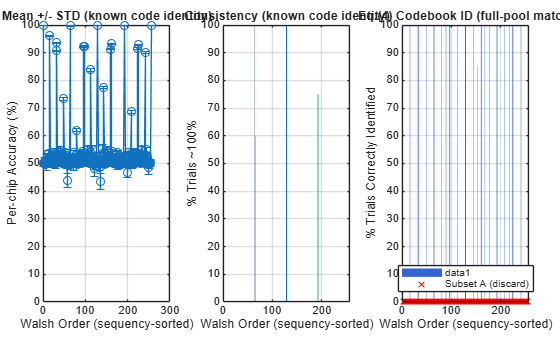

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1              100               0         100            100              0               0                 1     
         129                4               50          1.2287           0              0              1               1                29     
         193                6           50.137         0.75272           0              0              2             

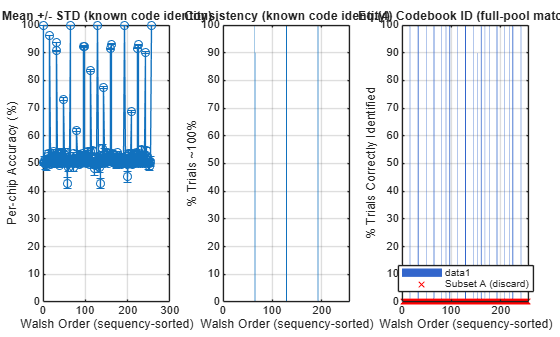

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1              100               0         100            100              0               0                 1     
         129                4           50.195         0.82621           0              0              1               1                29     
         193                6           50.293          1.0208           0              0              2             

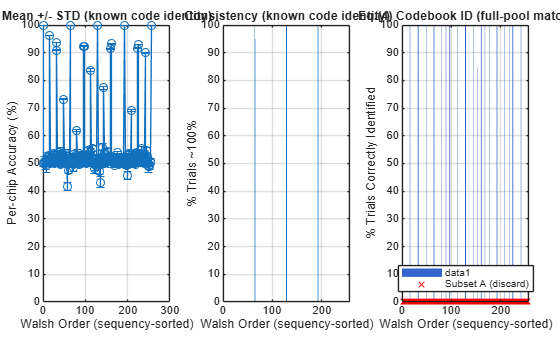

    SortedPosition    OriginalRow    MeanAccuracy    StdAccuracy    PctPerfect    PctIDCorrect    WalshScore    SubsetA_Discard    AccuracyRank
    ______________    ___________    ____________    ___________    __________    ____________    __________    _______________    ____________

           1                1              100               0         100            100              0               0                 1     
         129                4           50.039         0.97265           0              0              1               1                29     
         193                6           50.332         0.96747           0              0              2             


% PlotHadcheckStyle_Inline.mlx
resultsFolder = pwd; % change if needed
files = dir(fullfile(resultsFolder, 'fixed_hadamard_results_snr_*dB.csv'));
if isempty(files)
    error('No matching 9_2 CSV files found in %s', resultsFolder);
end

% Sort by the NUMERIC SNR embedded in the filename, not alphabetically.
% dir() returns names in string order, which puts "10dB"/"12dB"/"15dB"
% before "3dB"/"5dB"/"8dB" -- that scrambles the low-to-high SNR sequence.
snrNums = nan(numel(files), 1);
for k = 1:numel(files)
    tok = regexp(files(k).name, 'snr_(-?\d+)dB', 'tokens', 'once');
    if ~isempty(tok)
        snrNums(k) = str2double(tok{1});
    end
end
[~, fileOrder] = sort(snrNums);
files = files(fileOrder);

for k = 1:numel(files)
    T = readtable(fullfile(files(k).folder, files(k).name));

    % New export format (from the corrected hadfixed9_2) includes
    % SortedPosition, OriginalRow, PctIDCorrect, and SubsetA_Discard.
    % Fall back gracefully if an older-format CSV is encountered.
    req = {'MeanAccuracy','StdAccuracy','PctPerfect','WalshScore'};
    if ~all(ismember(req, T.Properties.VariableNames))
        warning('Skipping %s - missing required columns.', files(k).name);
        continue;
    end
    hasIDcorrect = ismember('PctIDCorrect', T.Properties.VariableNames);
    hasSubsetA = ismember('SubsetA_Discard', T.Properties.VariableNames);
    if ismember('SortedPosition', T.Properties.VariableNames)
        posCol = 'SortedPosition';
    else
        posCol = 'OriginalRow';  % older CSVs used this as the sorted position
    end

    % Reorder by WalshScore (sequency) like hadcheck
    T = sortrows(T, 'WalshScore', 'ascend');

    meanAcc = T.MeanAccuracy;
    stdAcc  = T.StdAccuracy;
    pctPerfect = T.PctPerfect;
    numRows = height(T);

    if hasIDcorrect
        pctIDcorrect = T.PctIDCorrect;
    end
    if hasSubsetA
        subsetA = T.SubsetA_Discard;
    end

    % Inline figure (Live Editor displays inline)
    fig = figure('Name', files(k).name, 'Color', 'w');
    sgtitle(fig, files(k).name, 'Interpreter', 'none');

    if hasIDcorrect
        t = tiledlayout(fig, 1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    else
        t = tiledlayout(fig, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    end

    ax1 = nexttile(t, 1);
    errorbar(ax1, 1:numRows, meanAcc, stdAcc, 'o-');
    xlabel(ax1, 'Walsh Order (sequency-sorted)');
    ylabel(ax1, 'Per-chip Accuracy (%)');
    title(ax1, 'Mean +/- STD (known code identity)');
    ylim(ax1, [0 100]);
    grid(ax1, 'on');

    ax2 = nexttile(t, 2);
    bar(ax2, 1:numRows, pctPerfect);
    xlabel(ax2, 'Walsh Order (sequency-sorted)');
    ylabel(ax2, '% Trials ~100%');
    title(ax2, 'Consistency (known code identity)');
    ylim(ax2, [0 100]);
    grid(ax2, 'on');

    if hasIDcorrect
        ax3 = nexttile(t, 3);
        bar(ax3, 1:numRows, pctIDcorrect, 'FaceColor', [0.2 0.4 0.8]);
        hold(ax3, 'on');
        if hasSubsetA
            % Mark Subset A (fails even on a noiseless channel) so it's visible
            % which codes are excluded from consideration regardless of SNR.
            discardIdx = find(subsetA);
            if ~isempty(discardIdx)
                plot(ax3, discardIdx, zeros(size(discardIdx)), 'rx', ...
                    'MarkerSize', 6, 'DisplayName', 'Subset A (discard)');
                legend(ax3, 'Location', 'south');
            end
        end
        hold(ax3, 'off');
        xlabel(ax3, 'Walsh Order (sequency-sorted)');
        ylabel(ax3, '% Trials Correctly Identified');
        title(ax3, 'Eq.(4) Codebook ID (full-pool match)');
        ylim(ax3, [0 100]);
        grid(ax3, 'on');
    end

    % Optionally display the table under the figure (Live Editor will show it inline)
    disp(T);
end